clear; close; clc;

%%%%%%%%% data aquizition %%%%%%%%%%
% state (X) should be columns of spatial variable and rows of snapshots.
% derivative (Xdot) should be the same shape as state.

load('Gluhareff_massAveDat_adiab.mat')
%state = [Density, FT, mdotExit, P1, P2, P3, Pcore, Pexit, Tcore, Texit, V1, V2, V3, Vexit]; % all currently available data
state = [P1,P2,P3,Pexit]; % pressure data
%state = [P1,P2,P3,Pexit,V1,V2,V3,Vexit];

%stateNames = {"Density", "FT", "mdotExit", "P1", "P2", "P3", "Pcore", "Pexit", "Tcore", "Texit", "V1", "V2", "V3", "Vexit"}; % all currently available data
stateNames = {"P1","P2","P3","Pexit"};
%stateNames = {"P1","P2","P3","Pexit","V1", "V2", "V3", "Vexit"};

% segment data into training test and validation sets
trainFrac = .7;
valFrac = .15;
testFrac = .15;
if(trainFrac+valFrac+testFrac ~= 1); disp("training, validation, and test fractions don't add up to 1."); end;

% I should possibly randomize the order of the data?
trainIndex = floor(trainFrac*length(state)); % last index of training set
valIndex= trainIndex + floor(valFrac*length(state)); % last index of validation set

%trainState = state(1:trainIndex,:);
trainState = state(400:trainIndex,:); % just steady state operation
valState = state(trainIndex:valIndex,:);
testState = state(valIndex:end,:);


%%%%%%%% compute derivative %%%%%%%%

dt = (TimeMilisec(2) - TimeMilisec(1)) / 1000; % find the timestep in seconds

% derivative(:,1) = TVRegDiff(trainState(:,1),10,.00002,[],"small",1e12,dt,0,1); %plot flag ste false to save time
% derivative(:,2) = TVRegDiff(trainState(:,2),10,.00002,[],"small",1e12,dt,0,1);
% derivative(:,3) = TVRegDiff(trainState(:,3),10,.00002,[],"small",1e12,dt,0,1);
% derivative(:,4) = TVRegDiff(trainState(:,4),10,.00002,[],"small",1e12,dt,0,1);
% derivative = derivative(1:end-1,:); % needed if scale set to small

for i = 1:size(state,2)
    derivative(:,i) = TVRegDiff(state(:,i),10,.00002,[],"small",1e12,dt,0,1); %plot flag ste false to save time
end

pcg converged at iteration 31 to a solution with relative residual 9.3e-05.
iteration    1: relative change = 4.735e+03, gradient norm = 7.683e-02
pcg converged at iteration 75 to a solution with relative residual 7.4e-05.
iteration    2: relative change = 1.268e-01, gradient norm = 7.164e-06
pcg converged at iteration 83 to a solution with relative residual 7e-05.
iteration    3: relative change = 1.491e-03, gradient norm = 4.853e-08
pcg converged at iteration 72 to a solution with relative residual 8.1e-05.
iteration    4: relative change = 4.194e-05, gradient norm = 1.946e-09
pcg converged at iteration 73 to a solution with relative residual 5.6e-05.
iteration    5: relative change = 1.423e-06, gradient norm = 7.884e-11
pcg converged at iteration 74 to a solution with relative residual 6.1e-05.
iteration    6: relative change = 5.235e-08, gradient norm = 3.192e-12
pcg converged at iteration 75 to a solution with relative residual 6.4e-05.
iteration    7: relative change = 2.004e-09,

derivative = derivative(1:end-1,:); % needed if scale set to small

%%% attemp a second order SINDy model by fitting the second derivative
%%% useing the first and state

state = [state, derivative]; % for second order
%trainState = state(1:trainIndex,:); % for second order
trainState = state(400:trainIndex,:); % just steady state operation
valState = state(trainIndex:valIndex,:); % for second order
testState = state(valIndex:end,:); % for second order
stateNames = {"P1","P2","P3","Pexit", "P1_dot","P2_dot","P3_dot","Pexit_dot"}; % for second order

derivative = []; % for second order
for i = 1:size(state,2) % for second order
    derivative(:,i) = TVRegDiff(trainState(:,i),10,.00002,[],"small",1e12,dt,0,1); %plot flag ste false to save time % for second order
end % for second order

pcg converged at iteration 23 to a solution with relative residual 7.1e-05.
iteration    1: relative change = 3.759e+03, gradient norm = 2.298e-04
pcg converged at iteration 34 to a solution with relative residual 8.7e-05.
iteration    2: relative change = 3.707e-03, gradient norm = 1.642e-08
pcg converged at iteration 36 to a solution with relative residual 7.5e-05.
iteration    3: relative change = 2.043e-07, gradient norm = 1.544e-12
pcg converged at iteration 34 to a solution with relative residual 8.7e-05.
iteration    4: relative change = 3.547e-11, gradient norm = 3.581e-16
pcg converged at iteration 35 to a solution with relative residual 6.6e-05.
iteration    5: relative change = 2.299e-14, gradient norm = 3.129e-19
pcg converged at iteration 32 to a solution with relative residual 9.2e-05.
iteration    6: relative change = 2.111e-14, gradient norm = 2.726e-19
pcg converged at iteration 32 to a solution with relative residual 8.4e-05.
iteration    7: relative change = 2.470e-1

derivative = derivative(1:end-1,:); % needed if scale set to small % for second order


%%%%%%%%% perform SINDy %%%%%%%%%%%

%%% generate library of nonlinear candidate functions (Theta)
% dimentions are (snapshots x potential functions) i.e. (rows x columns)

% list of functions we would like
requestedFunctions = ["const","linear","sin"]; % constant and linear terms

% declare library of candiate Functions
Theta = generateLibrary(trainState,requestedFunctions);

%%% generate the matrix of vecotrs of sparse coefficients (Xi)
% dimentions of Xi are (potential functions x spatial variables) i.e. (rows
% x columns) i.e. Xi = zeros(size(Theta,2),size(state,1))

% we have two sparsification knobs lambda1 and lambda2

% lambda1 is our threshold (sparsification knob) a value of 1 will be purely
% sparse (i.e. Xi will equal all 0s) and a value of 0 will be pure linear
% regresion (i.e. Xi = Theta \ Xdot)
lambda1  = .5;
% lambda2 is related the the ridge regression algorithm. a value of 0 will
% make it equivalent the least squares regression
lambda2 = .1;

Xi = STRidge(Theta,derivative,lambda1,lambda2); % perform the regression

disp(InterpretResults(stateNames,Xi,requestedFunctions)); % display the model generated

results = 170×9 cell array
    {0×0 char         }    {["P1"    "dot"]}    {["P2"    "dot"]}    {["P3"    "dot"]}    {["Pexit"    "dot"]}    {["P1_dot"    "dot"]}    {["P2_dot"    "dot"]}    {["P3_dot"    "dot"]}    {["Pexit_dot"    "dot"]}
    {1×1 cell         }    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[         690.5851]}    {[         -41.6246]}    {[      -1.5589e+03]}    {[             44.4304]}
    {["P1"           ]}    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[      -3.8082e+03]}    {[         -13.2721]}    {[      -4.7763e+03]}    {[             82.7412]}
    {["P2"           ]}    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[         374.3021]}    {[         -69.2941]}    {[      -1.2048e+03]}    {[            633.6125]}
    {["P3"           ]}    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[ 

    {0×0 char             }    {["P1"    "dot"]}    {["P2"    "dot"]}    {["P3"    "dot"]}    {["Pexit"    "dot"]}    {["P1_dot"    "dot"]}    {["P2_dot"    "dot"]}    {["P3_dot"    "dot"]}    {["Pexit_dot"    "dot"]}
    {1×1 cell             }    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[         690.5851]}    {[         -41.6246]}    {[      -1.5589e+03]}    {[             44.4304]}
    {["P1"               ]}    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[      -3.8082e+03]}    {[         -13.2721]}    {[      -4.7763e+03]}    {[             82.7412]}
    {["P2"               ]}    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[         374.3021]}    {[         -69.2941]}    {[      -1.2048e+03]}    {[            633.6125]}
    {["P3"               ]}    {[            0]}    {[            0]}    {[            0]}    {[               0]}    {[        


%%% SINDy algorithum is now complete %%%



## Interpret Results

%trainTimeMilis = TimeMilisec(1:trainIndex);
trainTimeMilis = TimeMilisec(400:trainIndex); % just ss operation
valTimeMilis = TimeMilisec(trainIndex:valIndex);
testTimeMilis = TimeMilisec(valIndex:end);
trainIC = trainState(1,:);
valIC = valState(1,:);
testIC = valState(1,:);

% set otions to alow for more accurate simulation and control of error tolerances
% set relative tolerance to 10^-12 and absoute tolerence of each component
% to the 10^-12
options = odeset('RelTol',1e-12, 'AbsTol',1e-12*ones(1,size(state,2)));

% simulate system model over the training validation and test regions
% i am very confident that it is actually regenerating the library each
% time the function is called
[~,trainModel] = ode45(@(t,x) SINDyGalerkin(t,x,Xi,requestedFunctions), trainTimeMilis, trainIC, options);
[~,valModel] = ode45(@(t,x) SINDyGalerkin(t,x,Xi,requestedFunctions), valTimeMilis, valIC, options);

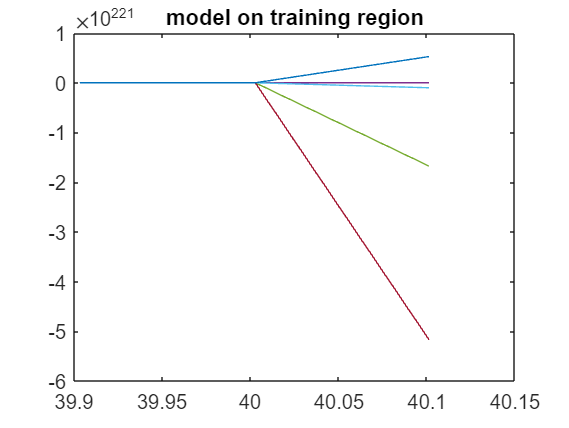

%[~,testModel] = ode45(@(t,x) SINDyGalerkin(t,x,Xi,requestedFunctions), testTimeMilis, testIC, options);

% plot training model vs data
%plot(TimeMilisec(1:trainIndex),trainModel); title("model on training region");
%plot(TimeMilisec(1:trainIndex),trainState); title("actual system training data");
plot(TimeMilisec(400:trainIndex),trainModel); title("model on training region"); % just steady state data

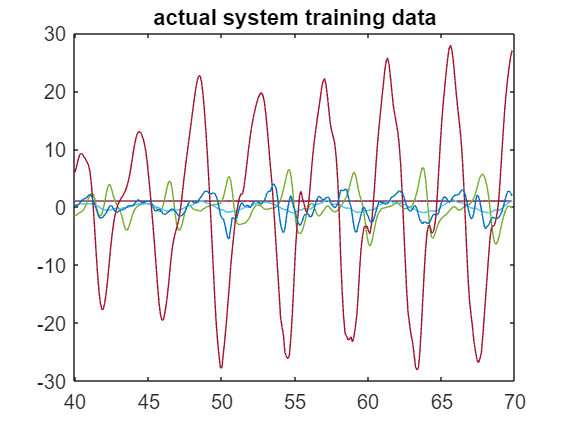

plot(TimeMilisec(400:trainIndex),trainState(1:end,:)); title("actual system training data"); % just steady state data


% plot validation model vs data
plot(TimeMilisec(trainIndex:valIndex),valModel); title("model on validation region");

Error using plot
Vectors must be the same length.

plot(TimeMilisec(trainIndex:valIndex),valState); title("actual system validation data");
